# Classification Workflow

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Load the pump features from `pumpFeatures.`

T = readtable("./data/pumpFeatures.csv");

Partition into training and testing

rng(0)
cv = cvpartition(size(T, 1), "HoldOut", 0.3);
dataTrain = T(cv.training, :);
dataTest = T(cv.test, :)

dataTest = 300×85 table
    wMotor_mean    wMotor_std    wMotor_fftPeakIdx    wMotor_skewness    wMotor_kurtosis    wMotor_peak2peak    wMotor_peak2rms    wMotor_rms    wMotor_mad    wMotor_csRange    wMotor_pLow    wMotor_pMid    wMotor_pHigh    wMotor_pKur    iMotor_mean    iMotor_std    iMotor_fftPeakIdx    iMotor_skewness    iMotor_kurtosis    iMotor_peak2peak    iMotor_peak2rms    iMotor_rms    iMotor_mad    iMotor_csRange    iMotor_pLow    iMotor_pMid    iMotor_pHigh    iMotor_pKur    qIn_mean   

## Task 1

To construct a classifier in MATLAB, use the `fitc___` function, replacing ___ with the name of the classifier. The inputs should be the data table and the name of the response variable.

For example, the following syntax creates a *k-*nearest neighbor (kNN) classification model.

`mdl` `=` `fitcknn``(``tableData``,``...`

    `"``ResponseVariable``"``)``;`

mdl = fitcknn(dataTrain, "faultCode");

## Task 2

The `predict` function determines the predicted class of new observations.

`predClass` `=` `predict``(``mdl``,``testData``)``;`

preds = predict(mdl, dataTest);

## Task 3

What proportion of points have been misclassified?

You can use the function `loss` to evaluate how well a model classifies the data.

`err` `=` `loss``(``mdl``,``testData``)`

The output consists of the inaccuracy of the classification model on the test data, a lower loss indicates a better predictive model.

err = loss(mdl, dataTest)

err = 0.1116

## Task 4

To visualize how the algorithm classified the observations, you can use the function `confusionchart`.

`confusionchart``(``trueLabels``,``predictions``)`

The result is a confusion matrix showing the number of observations for each combination of true and predicted class.

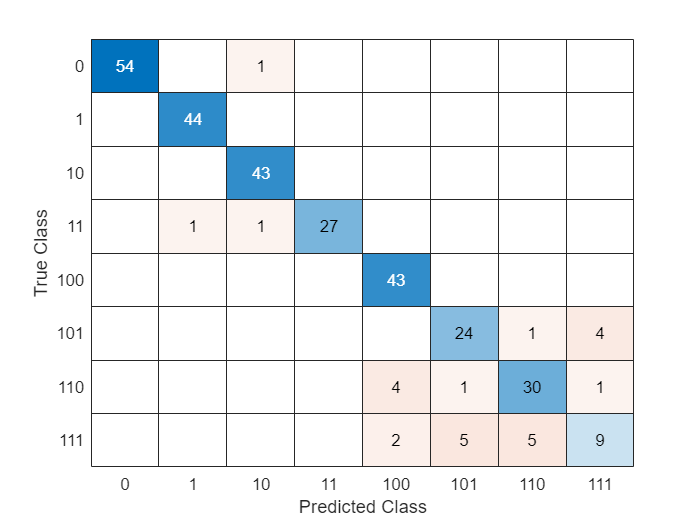

confusionchart(dataTest.faultCode, preds)